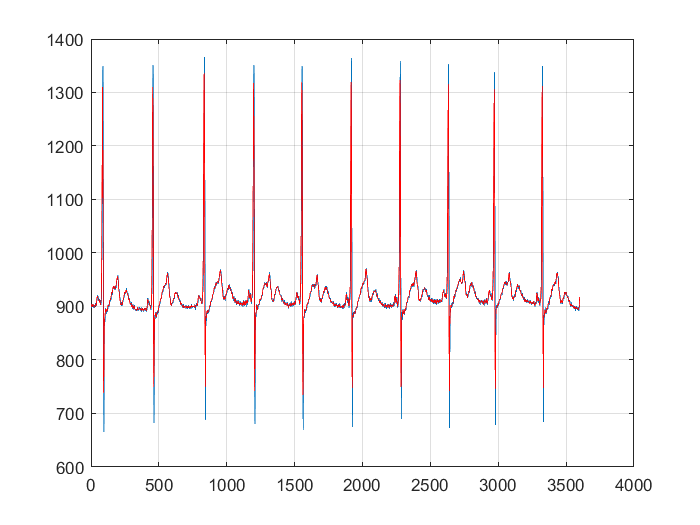

%data = rand(1,50);                          % Data
data =val; 
M = length(data);
fltr = ones(1,5);                           % Filter
F_length = length(fltr);
datax = [data ones(1,F_length)*mean(data)];     % Pad ‘data’ vector with ones*mean(data)
mavg = [];
for k1 = 1:M
    mavg = [mavg (fltr * datax(k1:k1+F_length-1)')/F_length];
end
figure(1)
plot([1:M], data)
hold on
plot([1:M], mavg, '-r')
hold off
grid

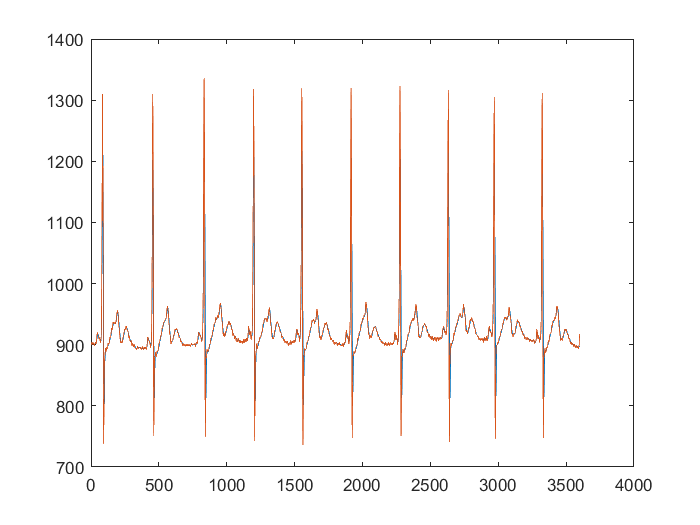

data1 = movmean(data,10);
figure(2)
plot([1:M],data1,[1:M],mavg);

%A=[1 2 3 4 5 6];
A = val;
M = length(A);
% N = 50;
% t = 0:0.001:50;
% data = cos(2*pi*10000*t);
m=ones(1,length(A));
for i=1:length(A)
    if i == 1
        m(i) = (A(i)+A(i+1))/2;
    elseif i == length(A)
        m(i) = (A(i-1)+A(i))/2;
    else
        m(i) = (A(i-1)+A(i)+A(i+1))/3;
    end
end
movmean(A,3)

ans = 	1.0e+03 *

    0.8985    0.8987    0.8990    0.9000    0.9013    0.9027    0.9037    0.9043    0.9047    0.9040    0.9033    0.9027    0.9020    0.9010    0.8997    0.8997    0.9000    0.9013    0.9020    0.9030    0.9030    0.9027    0.9023    0.9017    0.9013    0.8993    0.8983    0.8977    0.8990    0.9003    0.9027    0.9037    0.9050    0.9040    0.9037    0.9027    0.9020    0.9013    0.9010    0.9017    0.9030    0.9050    0.9077    0.9100    0.9137    0.9170    0.9197    0.9207    0.9203    0.9193


m

m = 	1.0e+03 *

    0.8985    0.8987    0.8990    0.9000    0.9013    0.9027    0.9037    0.9043    0.9047    0.9040    0.9033    0.9027    0.9020    0.9010    0.8997    0.8997    0.9000    0.9013    0.9020    0.9030    0.9030    0.9027    0.9023    0.9017    0.9013    0.8993    0.8983    0.8977    0.8990    0.9003    0.9027    0.9037    0.9050    0.9040    0.9037    0.9027    0.9020    0.9013    0.9010    0.9017    0.9030    0.9050    0.9077    0.9100    0.9137    0.9170    0.9197    0.9207    0.9203    0.9193


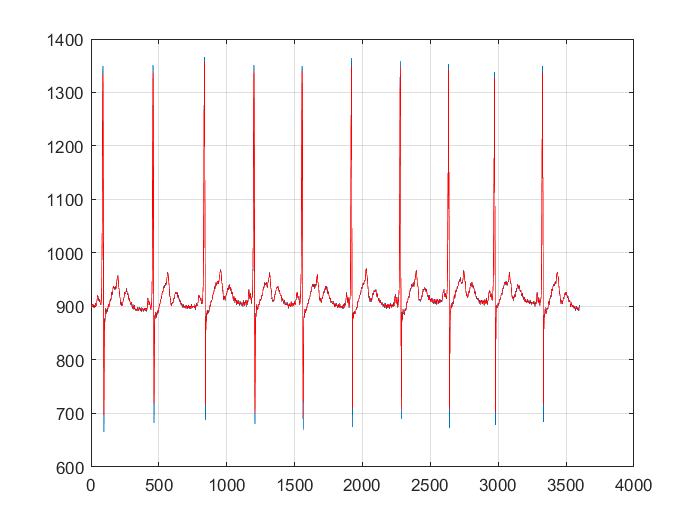

figure(1)
plot([1:M], A)
hold on
plot([1:M], m, '-r')
hold off
grid

data = [1, 1, 1, 1, 0, 0, 0, 0,1,3,4,5,6,7,8,1,4,3,5,6,7,8,9,3,1, 1, 1, 1, 0, 0, 0, 0];
data_fft = fft(data)

data_fft =   88.0000 + 0.0000i -48.4334 + 8.1103i   1.1522 - 5.0273i  27.0807 - 6.7416i -17.3137 + 4.5858i   3.3023 - 9.6250i   2.2346 - 1.4966i   4.4942 + 7.9764i  -8.0000 - 6.0000i   2.4785 + 1.3655i   3.7654 - 0.6682i  -3.9062 + 3.7724i   5.3137 - 7.4142i  -1.7072 + 3.8274i   4.8478 - 0.1989i  -7.3089 - 1.3290i   8.0000 + 0.0000i  -7.3089 + 1.3290i   4.8478 + 0.1989i  -1.7072 - 3.8274i   5.3137 + 7.4142i  -3.9062 - 3.7724i   3.7654 + 0.6682i   2.4785 - 1.3655i  -8.0000 + 6.0000i   4.4942 - 7.9764i   2.2346 + 1.4966i   3.3023 + 9.6250i -17.3137 - 4.5858i  27.0807 + 6.7416i   1.1522 + 5.0273i -48.4334 - 8.1103i
